Load Case Setup

%load case 1
lightest = 400/6

lightest = 66.6667

heaviest = 400/6

heaviest = 66.6667

loco = 400/6

loco = 66.6667




%load case 2A
lightest = 135 
lightest = lightest / 2
heaviest = lightest
loco = heaviest * 1.35


%load case 2B

lightest = 135 
lightest = lightest / 2
heaviest = lightest * 1.1
loco = heaviest * 1.35


case_loads = [heaviest heaviest lightest lightest loco loco]

case_loads =    66.6667   66.6667   66.6667   66.6667   66.6667   66.6667


total_loads = sum(case_loads)

total_loads = 400.0000

Envelope Solver

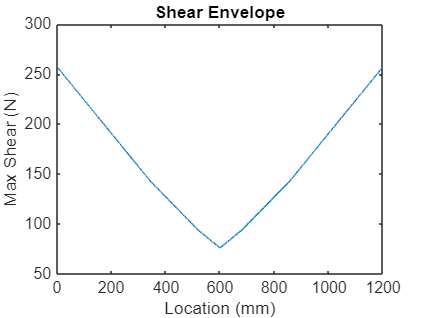

steps = 20560 + 1;

x = [linspace(-856, 1200, steps)];
%x is location of leftmost wheel

v_env = [linspace(0,1200,12001);zeros(steps,12001)];
m_env = [linspace(0,1200,12001);zeros(steps,12001)];
for j = 1:length(x)


first = x(j);


% calculate location of loads
loads = [case_loads; first + [0 176 340 516 680 856]];

% remove loads not on bridge
i_list = [];
for i = 1:length(loads(1,:))
    if loads(2,i) < 0 || loads(2,i) > 1200
        i_list = [i i_list];
    end
end

for i = i_list
    loads(:,i) = [];
end

% reaction forces
By = sum(loads(2,:).*loads(1,:))/1200;
Ay = sum(loads(1,:)) - By;
%V = max(Ay, By);
%x(2,j) = V;

% sfd
SFD = [Ay zeros(1, length(loads(1,:))); loads(2,1) zeros(1, length(loads(1,:))-1) 1200-loads(2, end)];
for i = 1:(length(loads(1,:)))
    SFD(1, i+1) = SFD(1, i) - loads(1, i);
end
for i = 1:length(loads(1,:))-1
    SFD(2, i+1) = loads(2,i+1) - loads(2,i);
end
SFD = [SFD;SFD(1,:).*SFD(2,:)];


locs = [loads(2,:) 1200];

SFD_exp = [linspace(0,1200,12001);zeros(1, 12001)];
for i = 1:length(SFD_exp(1,:))
    for k = 1:length(locs)
        if SFD_exp(1,i) <= locs(k)
            SFD_exp(2,i) = abs(SFD(1,k));
            break
        end
    end
end



v_env(j+1,:) = SFD_exp(2,:);

% bmd
BMD = [0 SFD(2,:);zeros(1,length(SFD(1,:))+1)];
for i = 2:length(SFD(1,:))+1
    BMD(2,i) = BMD(2, i-1) + SFD(3,i-1);
end



BMD_exp = [];

for k = 1:length(BMD(2,:))-1
    
    BMD_exp = [BMD_exp linspace(BMD(2,k),BMD(2,k+1),(BMD(1,k+1)) * 10 + 1)];
    if k ~= length(BMD(2,:))-1
        BMD_exp(end) = [];
    end
    
end

% bandaid fix to weird bug
if length(BMD_exp) == 12000
        BMD_exp = [BMD_exp, BMD_exp(end)];
end
BMD_exp;
BMD_exp = [linspace(0,1200,12001);BMD_exp];


m_env(j+1,:) = BMD_exp(2,:);

end

env_max = [linspace(0,1200,12001);zeros(2,12001)];
for g = 1:length(env_max(1,:))
    env_max(2,g) = max(v_env(2:end, g));
    env_max(3,g) = max(m_env(2:end, g));
end

% Shear and Moment Envelopes
plot(env_max(1,:), env_max(2,:))
title("Shear Envelope")
xlabel("Location (mm)")
ylabel("Max Shear (N)")

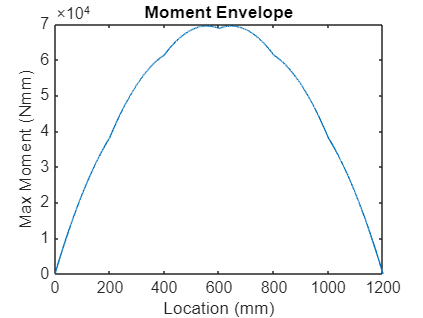

plot(env_max(1,:), env_max(3,:))
title("Moment Envelope")
xlabel("Location (mm)")
ylabel("Max Moment (Nmm)")

Set Variables

safe_tens = 30;
safe_comp = 6;
safe_shear_cent = 4;
safe_shear_glue = 2;

E = 4000;
poisson = 0.2;
E_mod = E / (1 - poisson^2);

Geometry

Design 0


b = [100 6.27 6.27 1.27 1.27 80];
h = [1.27 1.27 1.27 72.46 72.46 1.27];
y_knot = [75.635 74.365 74.365 37.5 37.5 0.635];

A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)

y_bar = 41.4311

I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

I = 4.1835e+05


%Q
b = [80 1.27 1.27];
h = [1.27 (y_bar - 1.27) (y_bar - 1.27)];
A = b.*h;
y_knot = [0.635 ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27)];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

Q_cent = 6.1933e+03


b = [100];
h = [1.27];
A = b.*h;
y_knot = [(75 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

Q_glue_1 = 4.3439e+03


b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(100 + 1.27 + 1.27/2) (75 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

Q_glue_2 = 1.1155e+04


h_total = 75 + 1.27;

b_cent = 2*1.27;
b_glue1 = 2*(5+1.27);

t1 = 1.27;
b1 = 80 - 1.27;
t2 = 1.27;
b2 = 10 + 1.27 / 2;
t3 = 1.27;
b3 = 75 - y_bar;
t4 = 1.27;
b4 = 75 - 1.27;


y_b3 = 75 - y_bar;


Design 1/3B

%{
b = [100 80 6.27 6.27 1.27 1.27 80];
h = [1.27 1.27 1.27 1.27 72.46 72.46 1.27];
y_knot = [76.905 75.635 74.365 74.365 37.5 37.5 0.635];

A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)
I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

%Q
b = [80 1.27 1.27];
h = [1.27 (y_bar - 1.27) (y_bar - 1.27)];
A = b.*h;
y_knot = [0.635 ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27)];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

b = [100];
h = [1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2) (75 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

h_total = 75 + 1.27 + 1.27;

b_cent = 2*1.27;
b_glue = 2*(5+1.27);

t1 = 1.27*2;
b1 = 80 - 1.27;
t2 = 1.27;
b2 = 10 + 1.27 / 2;
t3 = 1.27;
b3 = 75 - y_bar;
t4 = 1.27;
b4 = 75 - 1.27;


y_b3 = 75 - y_bar;
%}

Design 2

%{
b = [100 80 6.27 6.27 1.27 1.27 ];
h = [1.27 1.27 1.27 1.27 73.73 73.73 ];
y_knot = [76.905 75.635 74.365 74.365 36.865 36.865 ];

A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)
I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

%Q
b = [ 1.27 1.27];
h = [y_bar y_bar];
A = b.*h;
y_knot = [y_bar/2 y_bar/2];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

b = [100];
h = [1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2) (75 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

h_total = 75 + 1.27 + 1.27;

b_cent = 2*1.27;
b_glue = 2*(5+1.27);

t1 = 1.27*2;
b1 = 80 - 1.27;
t2 = 1.27;
b2 = 10 + 1.27 / 2;
t3 = 1.27;
b3 = 75 - y_bar;
t4 = 1.27;
b4 = 75 - 1.27;


y_b3 = 75 - y_bar;
%}

Design 3A

%{
b = [100 80 80 1.27 1.27 80];
h = [1.27 1.27 1.27 72.46 72.46 1.27];
y_knot = [76.905 75.635 74.365 37.5 37.5 0.635];

A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)
I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

%Q
b = [80 1.27 1.27];
h = [1.27 (y_bar - 1.27) (y_bar - 1.27)];
A = b.*h;
y_knot = [0.635 ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27)];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

b = [100];
h = [1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2) (75 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

h_total = 75 + 1.27 + 1.27;

b_cent = 2*1.27;
b_glue1 = 2*(5+1.27)
b_glue2 = 80;

t1 = 1.27*3;
b1 = 80 - 1.27;
t2 = 1.27;
b2 = 10 + 1.27 / 2;
t3 = 1.27;
b3 = 75 - 1.27 - y_bar;
t4 = 1.27;
b4 = 75 - 1.27;


y_b3 = 75 - y_bar;
%}

Design 4A

%{
b = [100 80 80 1.27 1.27 80];
h = [1.27 1.27 1.27 97.46 97.46 1.27];
y_knot = [101.905 100.635 99.365 50 50 0.635];

A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)
I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

%Q
b = [80 1.27 1.27];
h = [1.27 (y_bar - 1.27) (y_bar - 1.27)];
A = b.*h;
y_knot = [0.635 ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27)];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

b = [100];
h = [1.27];
A = b.*h;
y_knot = [(100 + 1.27 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(100 + 1.27 + 1.27/2) (100 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

h_total = 100 + 1.27 + 1.27;

b_cent = 2*1.27;
b_glue1 = 2*(5+1.27)
b_glue2 = 80;

t1 = 1.27*3;
b1 = 80 - 1.27;
t2 = 1.27;
b2 = 10 + 1.27 / 2;
t3 = 1.27;
b3 = 100 - y_bar;
t4 = 1.27;
b4 = 100 - 1.27;


y_b3 = 100 - y_bar;
%}

Design 4B/5B


b = [100 80 6.27 6.27 1.27 1.27 80];
h = [1.27 1.27 1.27 1.27 97.46 97.46 1.27];
y_knot = [101.905 100.635 99.365 99.365 50 50 0.635];

A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)
I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

%Q
b = [80 1.27 1.27];
h = [1.27 (y_bar - 1.27) (y_bar - 1.27)];
A = b.*h;
y_knot = [0.635 ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27)];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

b = [100];
h = [1.27];
A = b.*h;
y_knot = [(100 + 1.27 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(100 + 1.27 + 1.27/2) (100 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

h_total = 100 + 1.27 + 1.27;

b_cent = 2*1.27;
b_glue = 2*(5+1.27);

t1 = 1.27*2;
b1 = 80 - 1.27;
t2 = 1.27;
b2 = 10 + 1.27 / 2;
t3 = 1.27;
b3 = 100 - y_bar;
t4 = 1.27;
b4 = 100 - 1.27;


y_b3 = 100 - y_bar;

% for amalgamated design 5/6/7

y_bar_b = y_bar;
I_b = I;
Q_cent_b = Q_cent;
Q_glue_1_b = Q_glue_1;
Q_glue_2_b = Q_glue_2;
b3_b = b3;
b4_b = b4;
y_b3_b = y_b3;
b_cent_b = b_cent;
t1_b = t1;


Design 5A


b = [100 80 80 1.27 1.27 1.27 80];
h = [1.27 1.27 1.27 97.46 97.46 97.46 1.27];
y_knot = [101.905 100.635 99.365 50 50 50 0.635];

A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)
I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

%Q
b = [80 1.27 1.27 1.27];
h = [1.27 (y_bar - 1.27) (y_bar - 1.27) (y_bar - 1.27)];
A = b.*h;
y_knot = [0.635 ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27)];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

b = [100];
h = [1.27];
A = b.*h;
y_knot = [(100 + 1.27 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(100 + 1.27 + 1.27/2) (100 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

h_total = 100 + 1.27 + 1.27;

b_cent = 3*1.27;
b_glue1 = 2*(5+1.27)
b_glue2 = 80;

t1 = 1.27*3;
b1 = 80 - 1.27;
t2 = 1.27;
b2 = 10 + 1.27 / 2;
t3 = 1.27;
b3 = 100 - y_bar;
t4 = 1.27;
b4 = 100 - 1.27;


y_b3 = 100 - y_bar;

% for amalgamated design 5/6/7
y_bar_a = y_bar;
I_a = I;
Q_cent_a = Q_cent;
Q_glue_1_a = Q_glue_1;
Q_glue_2_a = Q_glue_2;
b3_a = b3;
b4_a = b4;
y_b3_a = y_b3;
b_cent_a = b_cent;
t1_a = t1;


Design 6

section_switch = 400;
a4 = 400;

Design 7

section_switch = 250;


Calculations

fos_env = [env_max(1,:);zeros(9, length(env_max(1,:)))];
forces_env = [env_max(1,:);zeros(9, length(env_max(1,:)))];
for lol = 1:length(env_max(1,:))

V_max = env_max(2,lol);
M_max = env_max(3,lol);


%check which section to use
if env_max(1, lol) <= section_switch || env_max(1, lol) >= 1200 - section_switch
    y_bar = y_bar_b;
    I = I_b;
    Q_cent = Q_cent_b;
    Q_glue_1 = Q_glue_1_b;
    Q_glue_2 = Q_glue_2_b;
    b3 = b3_b;
    b4 = b4_b;
    y_b3 = y_b3_b;
    b_cent = b_cent_b;
    t1 = t1_b;
else
    y_bar = y_bar_a;
    I = I_a;
    Q_cent = Q_cent_a;
    Q_glue_1 = Q_glue_1_a;
    Q_glue_2 = Q_glue_2_a;
    b3 = b3_a;
    b4 = b4_a;
    y_b3 = y_b3_a;
    b_cent = b_cent_a;
    t1 = t1_a;
end

%check diaphragm spacing for design 7
if env_max(1, lol) <= 100 || env_max(1, lol) >= 1200 - 100
    a4 = 100;
elseif env_max(1, lol) <= 250 || env_max(1, lol) >= 1200 - 250
    a4 = 150;
else
    a4 = 350;
end

%flexural
tens_stress = M_max * y_bar / I;
comp_stress = M_max * (h_total - y_bar) / I;

fos_tens =  safe_tens / tens_stress;
fos_comp =  safe_comp / comp_stress;

fos_env(2,lol) = fos_tens;
fos_env(3,lol) = fos_comp;

M_fail_tens = safe_tens * I / y_bar;
M_fail_comp = safe_comp * I / (h_total - y_bar);

forces_env(2,lol) = M_fail_tens;
forces_env(3,lol) = M_fail_comp;

stress_b1 = comp_stress;
stress_b2 = comp_stress;
stress_b3 = M_max * y_b3 / I;

%shear stress
shear_cent = (V_max * Q_cent) / (I * b_cent);
shear_glue_1 = (V_max * Q_glue_1) / (I * b_glue1);
shear_glue_2 = (V_max * Q_glue_2) / (I * b_glue2);

V_fail_cent = safe_shear_cent * I * b_cent / Q_cent;
V_fail_glue_1 = safe_shear_glue * I * b_glue1 / Q_glue_1;
V_fail_glue_2 = safe_shear_glue * I * b_glue2 / Q_glue_2;

forces_env(4,lol) = V_fail_cent;
forces_env(5,lol) = V_fail_glue_1;
forces_env(6,lol) = V_fail_glue_2;

fos_cent = safe_shear_cent / shear_cent;
fos_glue_1 = safe_shear_glue / shear_glue_1;
fos_glue_2 = safe_shear_glue / shear_glue_2;

fos_env(4,lol) = fos_cent;
fos_env(5,lol) = fos_glue_1;
fos_env(6,lol) = fos_glue_2;

%local buckling
buck_1 = 4 * pi^2 * E_mod / 12 * (t1 / b1)^2;
buck_2 = 0.425 * pi^2 * E_mod / 12 * (t2 / b2)^2;
buck_3 = 6 * pi^2 * E_mod / 12 * (t3 / b3)^2;
%w/o diaphragms
buck_4 = 5 * pi^2 * E_mod / 12 * ((t4 / b4)^2);
%with diaphragms 
%buck_4 = 5 * pi^2 * E_mod / 12 * ((t4 / b4)^2 + (t4 / a4)^2);

M_fail_buck_1 = buck_1 * I / y_bar;
M_fail_buck_2 = buck_2 * I / y_bar;
M_fail_buck_3 = buck_3 * I / y_b3;

forces_env(7,lol) = M_fail_buck_1;
forces_env(8,lol) = M_fail_buck_2;
forces_env(9,lol) = M_fail_buck_3;

V_fail_buck_4 = buck_4 * I * b_cent / Q_cent;
forces_env(10,lol) = V_fail_buck_4;


fos_b1 = buck_1 / stress_b1;
fos_b2 = buck_2 / stress_b2;
fos_b3 = buck_3 / stress_b3;
fos_b4 = buck_4 / shear_cent;

fos_env(7,lol) = fos_b1;
fos_env(8,lol) = fos_b2;
fos_env(9,lol) = fos_b3;
fos_env(10,lol) = fos_b4;
end


min_fos_tens = min(fos_env(2,:))

min_fos_tens = 4.3621

min_fos_comp = min(fos_env(3,:))

min_fos_comp = 1.0375

min_fos_cent = min(fos_env(4,:))

min_fos_cent = 2.6670

min_fos_glue1 = min(fos_env(5,:))

min_fos_glue1 = 9.3863

min_fos_glue2 = min(fos_env(6,:))

min_fos_glue2 = 0

min_fos_buck_1 = min(fos_env(7,:))

min_fos_buck_1 = 0.6168

min_fos_buck_2 = min(fos_env(8,:))

min_fos_buck_2 = 3.5914

min_fos_buck_3 = min(fos_env(9,:))

min_fos_buck_3 = 5.2815

min_fos_buck_4 = min(fos_env(10,:))

min_fos_buck_4 = 3.3897

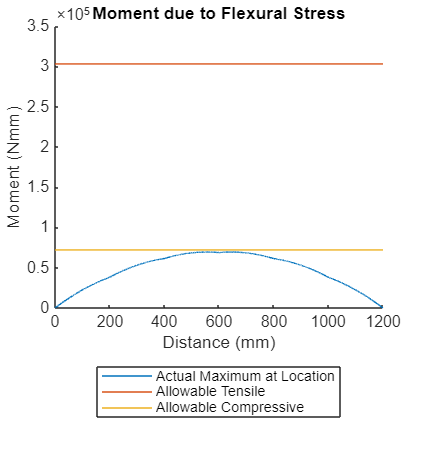


figure('Name','Measured Data');
% tension and compression
hold on
plot(fos_env(1,:), env_max(3,:))
plot(fos_env(1,:),forces_env(2,:))
plot(fos_env(1,:),forces_env(3,:))
hold off
title("Moment due to Flexural Stress")
legend("Actual Maximum at Location", "Allowable Tensile", "Allowable Compressive", "Location", "southoutside")
xlabel("Distance (mm)")
ylabel("Moment (Nmm)")
x0=10; y0=10; width=550; height=600 ;
set(gcf,'position',[x0,y0,width,height])

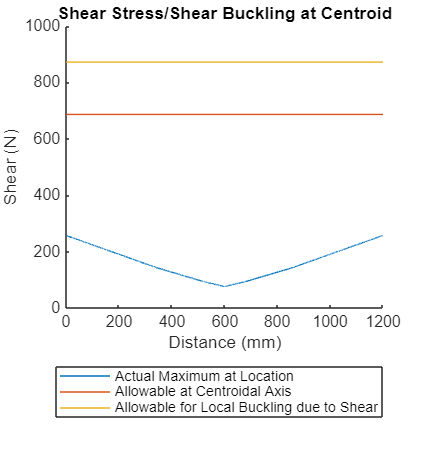


figure('Name','Measured Data');
% Shear Stress/Shear Buckling at Centroid
hold on
plot(fos_env(1,:), env_max(2,:))
plot(fos_env(1,:),forces_env(4,:))
plot(fos_env(1,:),forces_env(10,:))
hold off
x0=10; y0=10; width=550; height=600 ;
set(gcf,'position',[x0,y0,width,height])
title("Shear Stress/Shear Buckling at Centroid")
legend("Actual Maximum at Location", "Allowable at Centroidal Axis","Allowable for Local Buckling due to Shear", "Location", "southoutside")
xlabel("Distance (mm)")
ylabel("Shear (N)")


figure('Name','Measured Data');
% shear glue stress
hold on
plot(fos_env(1,:), env_max(2,:))
plot(fos_env(1,:),forces_env(5,:))
plot(fos_env(1,:),forces_env(6,:))
hold off
x0=10; y0=10; width=550; height=600 ;
set(gcf,'position',[x0,y0,width,height])
title("Shear Stress at Glue Locations")
legend("Actual Maximum at Location", "Allowable at Top Glue Layer", "Allowable at Middle Glue Layer",  "Location", "southoutside")

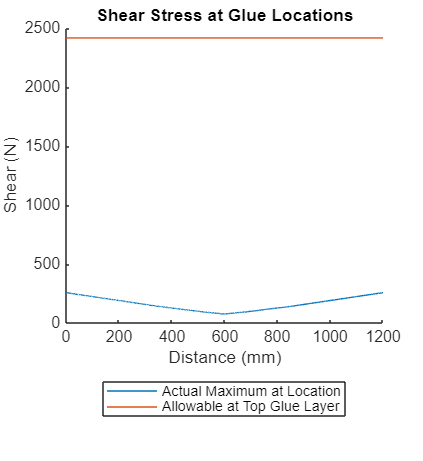

xlabel("Distance (mm)")
ylabel("Shear (N)")

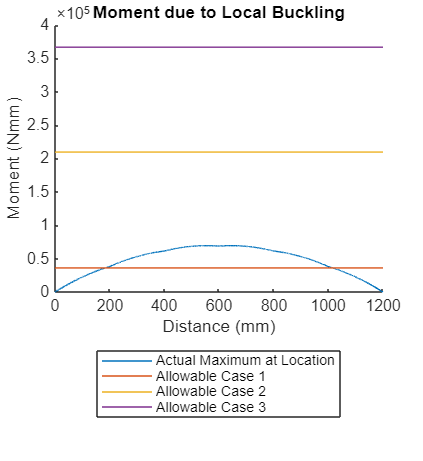


figure('Name','Measured Data');
% local compressive buckling
hold on
plot(fos_env(1,:), env_max(3,:))
plot(fos_env(1,:),forces_env(7,:))
plot(fos_env(1,:),forces_env(8,:))
plot(fos_env(1,:),forces_env(9,:))
hold off
title("Moment due to Local Buckling")
legend("Actual Maximum at Location", "Allowable Case 1", "Allowable Case 2", "Allowable Case 3", "Location", "southoutside")
xlabel("Distance (mm)")
ylabel("Moment (Nmm)")
x0=10; y0=10; width=550; height=600;
set(gcf,'position',[x0,y0,width,height])